imagedir = "simplearmory_images";

images = load_images(imagedir);

k = 10;
tile_size = 36;

image_folder = 'Test_Images';
image_filename = 'test1.jpg';  
image_path = fullfile(image_folder, image_filename);
base_image = im2double(imread(image_path));

for i = 1:numel(images)
    images{i} = imresize(images{i}, [tile_size, tile_size]);
end

%opt_images = optimize_images(images, k);
opt_images = optimize_images2(base_image, images, k);

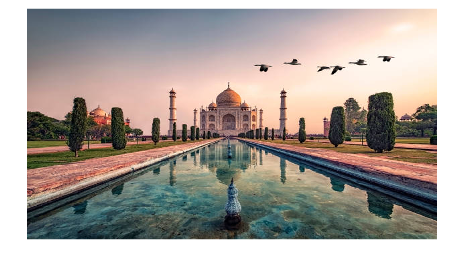



desired_base_size = [1440 2560]; 
base_image = imresize(base_image, desired_base_size);

reconstructed_image = reconstruct_image(base_image, opt_images, tile_size);
imshow(base_image)

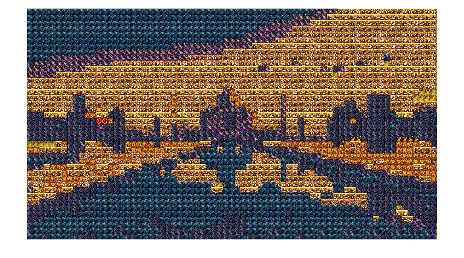

imshow(reconstructed_image);